# Composability of linear and nonlinear timewarping with respect to local relative rate

This script shows how a correct local relative rate can be obtained from the DTW warping curve of signals that have been linearly time-warped. This can be accomplished by modifying the indices of the DTW warping curve to account for the linear time-warping, prior to calculation of local relative rate.

#### Getting started

To run this livescript, you must have the DTWm and LRR_DTW repositories, available from [https://github.com/tilsen](https://github.com/tilsen)

Follow the instructions in the README file of the repository before running this script. 

%REQUIRED: this script should be run with its parent directory 
% and all of the parent's subdirectories on your path:
addpath(genpath('..')) 

%REQUIRED: the toolbox DTWm (https://github.com/tilsen/DTWm.git)
if ~contains(path,'DTWm')
    fprintf('toolbox DTWm required\n'); return;
end

#### Example signals

Here are three example signals generated from a logistic growth process, described by the differential equation:

    
$$\frac{dx_i(t)}{dt}=\left(g_i+w(t)\right)\cdot x_i(t)\cdot\left(1-\frac{x_i(t)}{L}\right)$$


where:

    
$$w(t)=\alpha_ie^{-t\beta}$$


The term $(g_i+w(t))$ is a time-varying growth rate. It has a constant component $g_i$ that differs among processes (indexed by $i$), and also a time-varying component $w(t)$ which decays or grows exponentially depending on the sign of $\alpha_i$. The parameter $\beta$ governs how quickly this time-varying component changes.

Generate the signals and obtain the ground truth instantaneous rates:

L = 1;                  % logistic growth limit
endval = 0.95;  % endpoint value of signals
x0 = 0.1;          % initial value
dt = 1e-3;          % time step
g = [2 2 3];        % constant component of growth rates
t = 0:dt:10;       % time vector

alpha = [0 1 -2]; % amplitude of time-varying nonlinear perturbation of growth rate
beta = 1; %timescale of nonlinear perturbation

N = numel(g); %number of signals

X={}; T={}; R={}; W={};
for i=1:N

    w = alpha(i)*exp(-t*beta);		% time-varying nonlinear perurbation of growth rates
    growth_rate = g(i)+w;

    x = zeros(1,length(t));
    x(1) = x0;
    for j=2:length(t)
        dx =  growth_rate(j-1)*x(j-1)*(1-x(j-1)/L);
        x(j) = x(j-1) + dx*dt;
    end

    ix_end = find(x>=endval,1,'first');

    X{i} = x(1:ix_end); %signals
    T{i} = t(1:ix_end);   %time  vectors
    r = gradient(x)/dt; %instantaneous signal change rates
    R{i} = r(1:ix_end); 
    W{i} = w(1:ix_end); %time-varying nonlinear perturbations of rate

end

Plot the signals and change rates

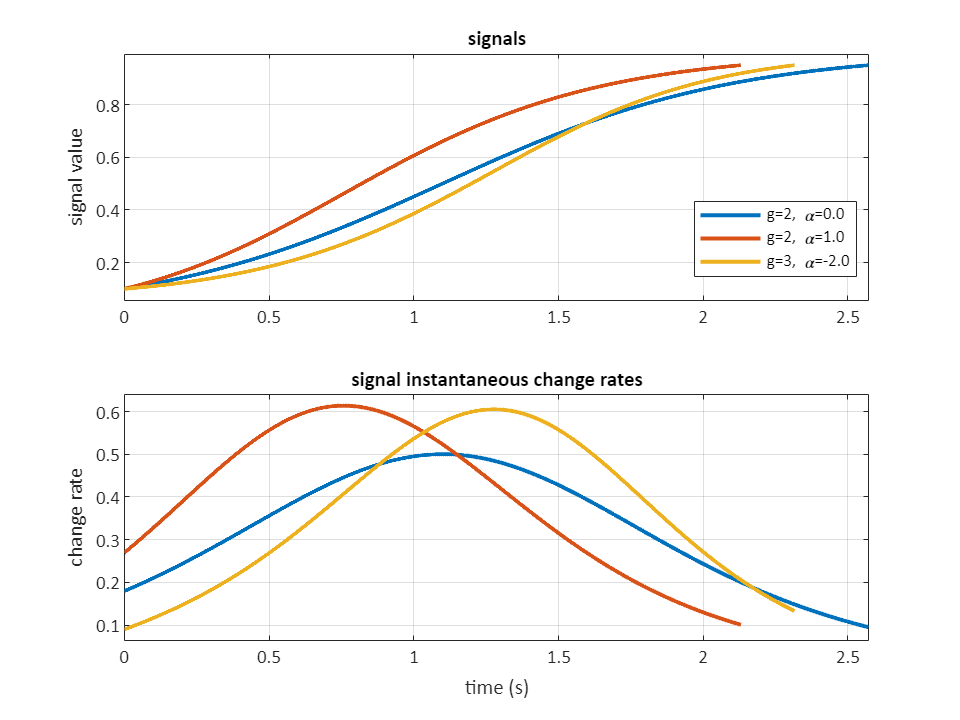

[ax,ph] = plot_signals(T,X,R);
title(ax(1),'signals'); title(ax(2),'signal instantaneous change rates');
ylabel(ax(1),'signal value'); ylabel(ax(2),'change rate');  xlabel('time (s)');
siglabs = arrayfun(@(c,d){sprintf('g=%1.0f, \\alpha=%1.1f',c,d)},g,alpha);
legend(ph(1,:),siglabs,'Location','best');

#### Known (ground truth) relative rate

The ground truth local relative rate for any two monotonic functions is the ratio of the instantaneous change rates, where one signal is taken as a comparison and the other as a target.

However, the definition of the ground truth relative rate is not as simple as taking a ratio of these rates, since the rate timeseries are of different lengths. Thus they have to be matched in an appropriate way. This can be acheived with an asymmetric alignment, using the the DTW warping curve. 

Thus the known relative rate is the ratio of the instantaneous change rate of the target $R_t$ to the instantaneous change rate of the comparison $R_c$, after the comparison $R_c$ is aligned to the target $R_t$, using the DTW mapping of the target signal and comparison signals asymmetrically (such that the time coordinate of the target is adopted):

maps = dtwm_pairwise(X); %warping functions

rel_R={};
for a=1:N
    for b=1:N
        [~,~,map_comp] = align_signals(maps{a,b},X{a},X{b},'aligntype','reference');
        rel_R{a,b} =R{a}./ R{b}(map_comp(2,:));  %ratio of instantaneous change rates
        rel_W{a,b} = W{a}./W{b}(map_comp(2,:)); %ratio of nonlinear components of growth rate
    end
end

Plot the known relative rates

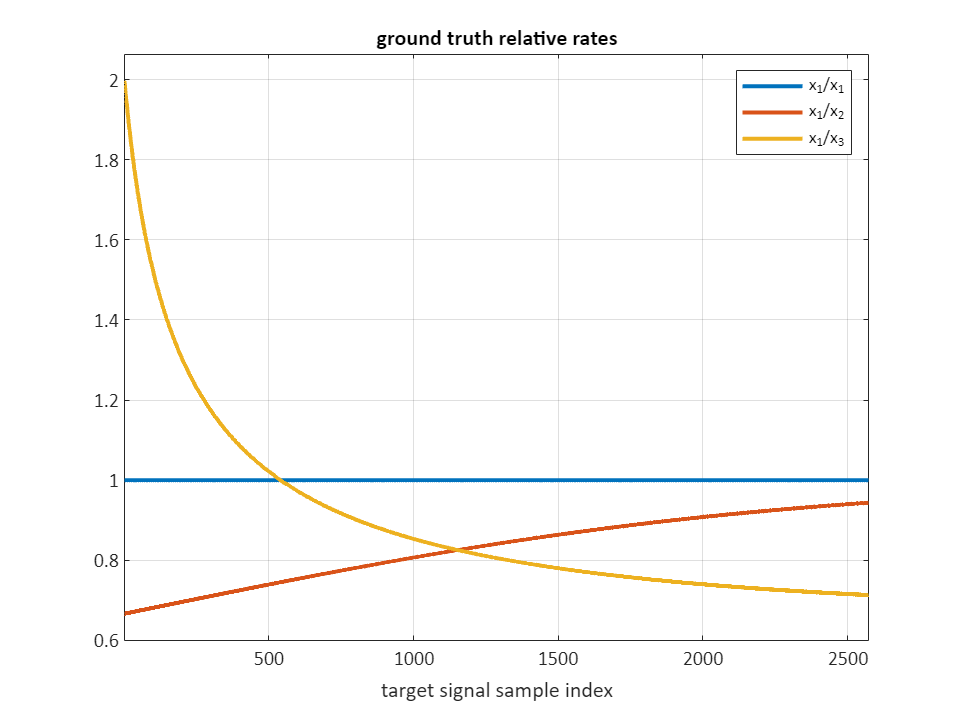

targix =1; %select one signal as the target
[ax,ph] = plot_signals([],rel_R(targix,:));
title(ax,'ground truth relative rates');  xlabel('target signal sample index');
legend(ph,arrayfun(@(c){sprintf('x_{%d}/x_%d',targix,c)},1:3),'location','best');

#### Standard DTW-based local relative rate

Calculate the LRR pairwise between signals:

LRR_dtw = lrr_pairwise(X);

Compare the DTW-based and ground truth relative rates:

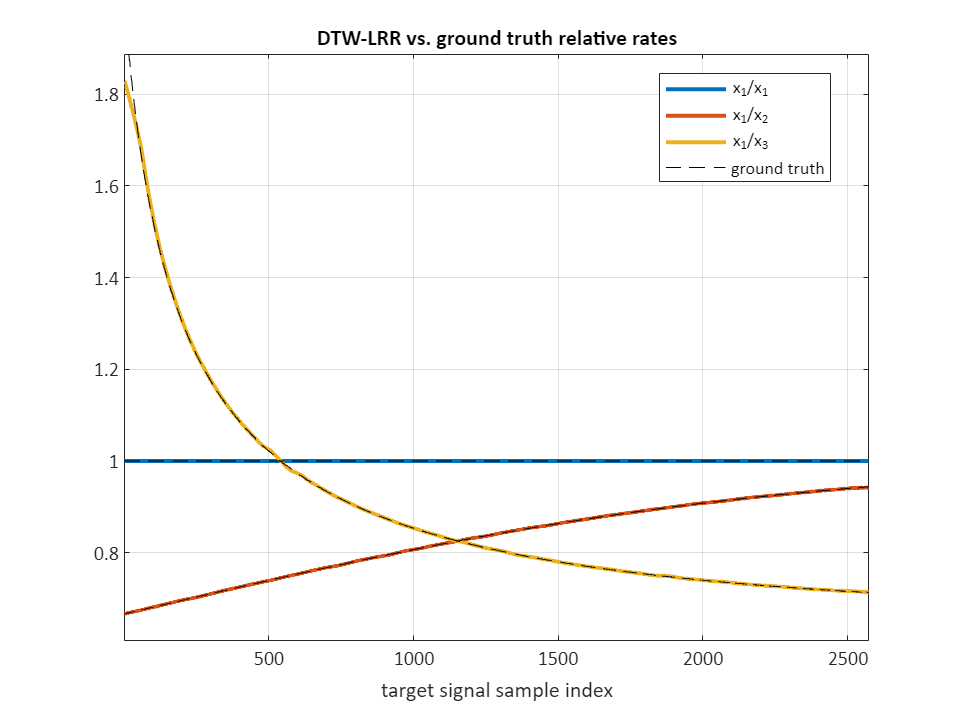

[ax,ph] = plot_signals([],LRR_dtw(targix,:));
for i=1:N, ph(end+1) = plot(rel_R{targix,i},'k--'); end
title(ax,'DTW-LRR vs. ground truth relative rates');  xlabel('target signal sample index');
legend(ph(1:N+1),[arrayfun(@(c){sprintf('x_{%d}/x_%d',targix,c)},1:3) {'ground truth'}],'location','best');

The DTW-LRR of the target signal to each of the comparisons closely matches the empirically calculated ground truths. The deviations near the beginning and ends are edge-effects due to the necessity of using a window to calculate the local slope:.

#### Obtaining local relative rate from signals that have been linearly time-warped

Perform an initial linear time-warping on signals and save the linear warping factors. Here we warp the signals to the median length:

med_len = median(cellfun(@(c)length(c),X));
for i=1:length(X)
    X_lw{i} = interp1(1:numel(X{i}),X{i},linspace(1,numel(X{i}),med_len));
    lw_fac(i) = med_len/numel(X{i});    
end

Obtain warping functions from DTW:

maps = dtwm_pairwise(X_lw);

Here are the local relative rates without adjusting for the initial linear normalization:

for a=1:N
    for b=1:N
            LRR_unadj{a,b} = lrr(maps{a,b} );
    end
end

Comparing the unadjusted LRRs it is clear that they do not match the ground truth:

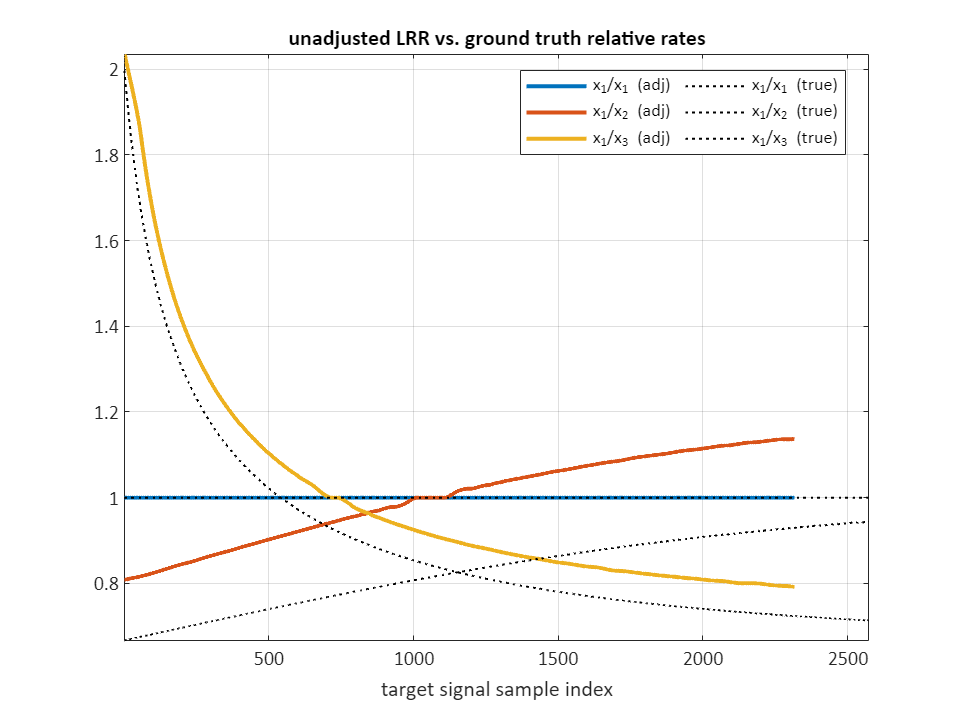

[ax,ph] = plot_signals([],LRR_unadj(targix,:));
colors = lines(N);
for i=1:N, ph(end+1) = plot(rel_R{targix,i},'k:','linew',1); end
axis(ax,'tight');
title(ax,'unadjusted LRR vs. ground truth relative rates');  xlabel('target signal sample index');
legstrs = [arrayfun(@(c){sprintf('x_{%d}/x_%d (adj)',targix,c)},1:3) ...
    arrayfun(@(c){sprintf('x_{%d}/x_%d (true)',targix,c)},1:3)];
legend(ph,legstrs,'location','best','NumColumns',2);

To adjust for the initial linear time warping, the indices of warping functions are multiplied by the inverse of the linear warping factors:

for a=1:N
    for b=1:N
            LRR_adj{a,b} = lrr(maps{a,b} ./ lw_fac([a b])');
    end
end

Compare the adjusted LRRs and ground truth relative rates:

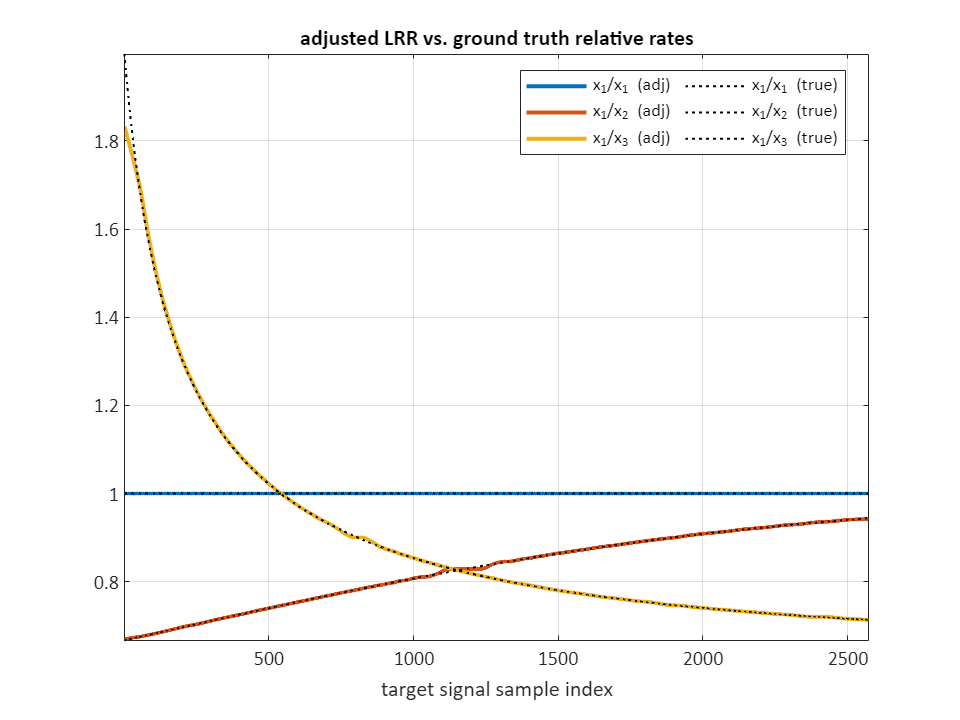

[ax,ph] = plot_signals([],LRR_adj(targix,:));
colors = lines(N);
for i=1:N, ph(end+1) = plot(rel_R{targix,i},'k:','linew',1); end
axis(ax,'tight');
title(ax,'adjusted LRR vs. ground truth relative rates');  xlabel('target signal sample index');
legstrs = [arrayfun(@(c){sprintf('x_{%d}/x_%d (adj)',targix,c)},1:3) ...
    arrayfun(@(c){sprintf('x_{%d}/x_%d (true)',targix,c)},1:3)];
legend(ph,legstrs,'location','best','NumColumns',2);

Notice that the relative rates obtained from the adjusted warping functions match the ground truth rates.

function [h] = figls()
h = figure('units','pixels','position',[0 0 640 480]);
end

function [ax,ph] = plot_signals(T,varargin)
h = figls;
P = numel(varargin);
for i=1:P
    ax(i) = subplot(P,1,i);
    X = varargin{i};
    N = numel(X);
    colors = lines(N);
    for j=1:N
        if isempty(T)
            ph(i,j) = plot(X{j},'linew',2,'color',colors(j,:)); hold on;
        else
            ph(i,j) = plot(T{j},X{j},'linew',2,'color',colors(j,:)); hold on;
        end
    end
    axis tight;
    ylim(ylim+0.05*diff(ylim)*[-1 1]);
    set(gca,'xgrid','on','ygrid','on');
end

end